# リーマンゼータ関数と作用素の固有値


$$Tr(x^N\partial ^N(-1)^\theta )=\frac12N!\left(-\frac12\right)^N$$


$S_{II}:$第二種Stirling数


$$Tr(\theta ^n(-1)^\theta )=0^n+(2^{1+n}-1)\zeta (-n)=\frac12\sum_{k=0}^nS_{II}(n,k)k!\left(-\frac12\right)^k$$



$$Tr(\theta ^nz^\theta )=0^n+\Psi_{-n}(z)=\frac1{1-z}\sum_{k=0}^nS_{II}(n,k)k!\left(\frac{z}{1-z}\right)^k\qquad (n\in \mathbb N)$$


N=10;
e1=zeros(1,N);
for n=0:length(e1)
    ii=sym(0:n);
    e1(n+1)=(factorial(ii).*(-1/2).^ii)/2*stirling2(n,ii,'sym').';  
end
n=0:N;
[e1;(2.^n*2-1).*zeta0(-n);polylog(-n,-1)]

ans =     0.5000   -0.2500         0    0.1250         0   -0.2500         0    1.0625         0   -7.7500         0
    0.5000   -0.2500         0    0.1250         0   -0.2500         0    1.0625         0   -7.7500         0
   -0.5000   -0.2500         0    0.1250         0   -0.2500         0    1.0625         0   -7.7500         0


N=10;
z=2;
e1=zeros(1,N);
for n=0:length(e1)
    ii=sym(0:n);
    e1(n+1)=(factorial(ii).*(z/(1-z)).^ii)*stirling2(n,ii,'double').'/(1-z);  
end
n=0:N;
[e1;polylog(-n,z)]


$$\sum_k(S_I(m,k))(S_{II}(k,m)(-1)^{k+m})=\delta_{mn}$$


stirling1(0:3,0:3,"double")*((-1).^((0:3)'+(0:3)).*stirling2(0:3,0:3,"double"))


$$\binom{x}{n}=\frac1{n!}\sum_{k=0}^nS_{I}(n,k)(-1)^{n+k}}x^{n-k}$$


N=4;
ii=0:N;
figure
fplot(@(x)gamma(x+1)./gamma(x-N+1)/factorial(N))
hold on
fplot(@(x)arrayfun(@(y)(-1).^ii.*y.^ii*stirling1(N,ii).'/factorial(N)*(-1)^N,x))

## Abaloneの計算の最終ステップ


$$\left[\begin{array}{c}
n\\m
\end{array}\right]_{\exp \hbar}=\binom nm\left(1+\frac{\hbar^2}{6}m(n+1)(n-m)\left(1+\frac{\hbar^2}{60}((5m - 2) n^2 - (m - 1)(5m - 2) n - {7} m^2)\right)\right)+o(\hbar^6)$$



$$Z\left({\mathbb{S}}^3 \;;U_{\hbar } \left({\textrm{sl}}_2^+ \right)\right)=\textrm{Tr}\left(\sum_{n\ge 0} q^{-n^2 +4n+\left(n-2\right)\theta } {\left\lbrack \begin{array}{c}
\theta \\
n
\end{array}\right\rbrack }_q \right)=^? q^2$$



$$\textrm{Tr}\left(\sum_{n\ge 0} q^{3n^2 +5n-\left(n+2\right)\theta } {\left\lbrack \begin{array}{c}
\theta \\
n
\end{array}\right\rbrack }_q \right)=^? q^{-1}$$



$$\sum_{n\ge 0} q^{-n^2 +4n+\left(n-2\right)\theta } {\left\lbrack \begin{array}{c}
\theta_z \\
n
\end{array}\right\rbrack }_q \cdot \frac{1}{1-z}$$



$$\textrm{Tr}\left(\sum_{n\ge 0} q^{3n^2 +\left(4-u\right)n-\left(n+2\right)\theta } {\left\lbrack \begin{array}{c}
\theta \\
n
\end{array}\right\rbrack }_q \right)=^? q^u$$



$$\textrm{Tr}\left(\sum_{n\ge 0} q^{-n^2 +\left(2+u\right)n+\left(n-u\right)\theta } {\left\lbrack \begin{array}{c}
\theta \\
n
\end{array}\right\rbrack }_q \right)=\sum_{n\ge 0} q^{-n^2 +\left(2+u\right)n+\left(n-u\right)\theta } {\left\lbrack \begin{array}{c}
\theta \\
n
\end{array}\right\rbrack }_q \frac{1}{1-y}|_{y=1} =^? q^u$$



$$\textrm{Tr}\left(_3 \phi_0 \left\lbrack \begin{array}{cc}
 & \\
 & 
\end{array}\right\rbrack \right)$$



$$\textrm{sgn}\left(1-a\right)=\left\lbrace \begin{array}{ll}
-１ & \left(a>1\right)\\
1 & \left(a<1\right)
\end{array}\right.$$



$$$\mathrm{Tr}\left({}_3 \phi_0 \left\lbrack \begin{array}{cc}
 0,0,q^{-\theta} \\
 -
\end{array};q;q^{-2-t}\right\rbrack q^{\theta} \right)=q^t$$$


を計算する必要がある

z=1;
syms n1 th hb u1
e11=exp(hb*(-n1^2+(2+u1)*n1+(-u1+n1)*th))*(1+hb^2*n1*(th+1)*(th-n1)/6*(1+hb^2*((5*n1-2)*(th-n1+1)*th-7*n1^2)/60));
e1=taylor(e11,hb,Order=6);%hbar展開
% e1=1+hb*(3*n1^2+5*n1-(n1+2)*th);
e2=fliplr(coeffs(e1,hb,'all'));%hb各項
r1=length(e2);%hb次数
e5=e2;%hbについての作用素の展開
e7=e2;%hbのついてのtraceの展開
for i1=1:r1%hb各項で計算
    e4=fliplr(coeffs(e2(i1),n1,'all'));%n1:作用素の和
    r2=0:length(e4)-1;
    e6=e4*stirling2(r2,r2);
    e6=e6.*(z/(1+z)).^r2*(factorial(r2).*binom(th,r2)).';
    e5(i1)=e6;
    e8=fliplr(coeffs(e6,th,'all'));
    e7(i1)=sign(-z)*sum(polylog0(-(0:length(e8)-1),1+z).*e8);

end
SI(e5)
SI(e7)

SI(e1)

$$ans = \begin{array}{l} \left({\sigma_{1}}^{4}\,\left(\frac{\mathrm{th}\,\left(n_{1}-u_{1}\right)}{120}+\frac{n_{1}\,\left(u_{1}+2\right)}{120}-\frac{{n_{1}}^{2}}{120}\right)+\frac{n_{1}\,\sigma_{2}\,\left(n_{1}-\mathrm{th}\right)\,\left(\mathrm{th}+1\right)\,\sigma_{1}}{6}-\frac{n_{1}\,\left(n_{1}-\mathrm{th}\right)\,\left(\mathrm{th}+1\right)\,{\sigma_{1}}^{2}\,\sigma_{3}}{6}\right)\,{\mathrm{hb}}^{5}+\left({\sigma_{1}}^{3}\,\left(\frac{\mathrm{th}\,\left(n_{1}-u_{1}\right)}{24}+\frac{n_{1}\,\left(u_{1}+2\right)}{24}-\frac{{n_{1}}^{2}}{24}\right)+\frac{n_{1}\,\sigma_{2}\,\left(n_{1}-\mathrm{th}\right)\,\left(\mathrm{th}+1\right)}{6}-\frac{n_{1}\,\left(n_{1}-\mathrm{th}\right)\,\left(\mathrm{th}+1\right)\,\sigma_{1}\,\sigma_{4}}{6}\right)\,{\mathrm{hb}}^{4}+\left({\sigma_{1}}^{2}\,\sigma_{3}-\frac{n_{1}\,\left(n_{1}-\mathrm{th}\right)\,\left(\mathrm{th}+1\right)\,\sigma_{1}}{6}\right)\,{\mathrm{hb}}^{3}+\left(\sigma_{1}\,\sigma_{4}-\frac{n_{1}\,\left(n_{1}-\mathrm{th}\right)\,\left(\mathrm{th}+1\right)}{6}\right)\,{\mathrm{hb}}^{2}+\sigma_{1}\,\mathrm{hb}+1\\ \mathrm{where}\\ \sigma_{1}=\mathrm{th}\,\left(n_{1}-u_{1}\right)+n_{1}\,\left(u_{1}+2\right)-{n_{1}}^{2}\\ \sigma_{2}=\frac{7\,{n_{1}}^{2}}{60}-\frac{\mathrm{th}\,\left(5\,n_{1}-2\right)\,\left(\mathrm{th}-n_{1}+1\right)}{60}\\ \sigma_{3}=\frac{\mathrm{th}\,\left(n_{1}-u_{1}\right)}{6}+\frac{n_{1}\,\left(u_{1}+2\right)}{6}-\frac{{n_{1}}^{2}}{6}\\ \sigma_{4}=\frac{\mathrm{th}\,\left(n_{1}-u_{1}\right)}{2}+\frac{n_{1}\,\left(u_{1}+2\right)}{2}-\frac{{n_{1}}^{2}}{2} \end{array}$$

syms z
qN=qNumS();
expr=0;
for ii=0:4
    expr=expr+SI(qN.q^(3*ii^2+5*ii-(ii+2)*z)*qN.binomial(z,ii));
end
factor(SI(expr)).'

$$ans = \begin{array}{l} \left(\begin{array}{c} q^{8\,z}+q^{84}-q^{8\,z}\,q^{2}-q^{8\,z}\,q^{4}+q^{6\,z}\,q^{9}-q^{8\,z}\,q^{9}+2\,q^{8\,z}\,q^{10}-q^{6\,z}\,q^{13}-q^{6\,z}\,q^{15}+q^{8\,z}\,q^{13}-q^{6\,z}\,q^{17}+q^{8\,z}\,q^{15}-q^{8\,z}\,q^{16}+q^{6\,z}\,q^{19}+q^{8\,z}\,q^{17}-q^{8\,z}\,q^{18}+q^{6\,z}\,q^{21}-q^{8\,z}\,q^{19}+q^{8\,z}\,q^{20}+q^{6\,z}\,q^{23}-q^{8\,z}\,q^{21}+q^{4\,z}\,q^{26}-q^{6\,z}\,q^{24}-q^{8\,z}\,q^{23}-q^{6\,z}\,q^{26}+q^{8\,z}\,q^{24}-q^{6\,z}\,q^{27}+q^{8\,z}\,q^{27}-q^{4\,z}\,q^{32}+q^{6\,z}\,q^{30}-q^{4\,z}\,q^{34}+2\,q^{6\,z}\,q^{32}-q^{8\,z}\,q^{30}+q^{6\,z}\,q^{34}-q^{8\,z}\,q^{32}+q^{4\,z}\,q^{40}-q^{6\,z}\,q^{38}-q^{6\,z}\,q^{40}+q^{8\,z}\,q^{38}-q^{4\,z}\,q^{47}+q^{6\,z}\,q^{45}+q^{2\,z}\,q^{51}-q^{4\,z}\,q^{49}+q^{6\,z}\,q^{47}-q^{8\,z}\,q^{45}-q^{4\,z}\,q^{51}+q^{6\,z}\,q^{49}+q^{4\,z}\,q^{55}-q^{6\,z}\,q^{53}-q^{2\,z}\,q^{59}+q^{4\,z}\,q^{57}-q^{6\,z}\,q^{55}+q^{8\,z}\,q^{53}+q^{4\,z}\,q^{59}-q^{6\,z}\,q^{57}+q^{4\,z}\,q^{74}-q^{6\,z}\,q^{72}-q^{2\,z}\,q^{78}+q^{4\,z}\,q^{76}-q^{6\,z}\,q^{74}+q^{8\,z}\,q^{72}-q^{2\,z}\,q^{80}+2\,q^{4\,z}\,q^{78}-q^{6\,z}\,q^{76}-q^{2\,z}\,q^{82}+q^{4\,z}\,q^{80}-q^{6\,z}\,q^{78}-q^{2\,z}\,q^{84}+q^{4\,z}\,q^{82}\\ \sigma_{1}\\ \sigma_{1}\\ \sigma_{1}\\ \sigma_{1}\\ \sigma_{1}\\ \frac{1}{q^{4}+1}\\ \frac{1}{q^{2}-q+1}\\ \frac{1}{q^{2}+q+1}\\ \sigma_{2}\\ \sigma_{2}\\ \frac{1}{q-1}\\ \frac{1}{q-1}\\ \frac{1}{q-1}\\ \frac{1}{q-1}\\ \frac{1}{q+1}\\ \frac{1}{q+1}\\ \frac{1}{q+1}\\ \frac{1}{q+1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{q^{2\,z}}\\ \sigma_{2}=\frac{1}{q^{2}+1} \end{array}$$

syms z
cf=fliplr(coeffs(z^3+2*z^2,'All'));
cf=stirling2(0:length(cf)-1,0:length(cf)-1).'*cf.'
SI(binom(z,3)*6+5*binom(z,2)*2+3*binom(z,1))

expr=0;
for n=0:50
    expr=expr+log(2)^n*zeta0(-n)/factorial(n);
end
expr

expr = 0.4427


$$\sum_{n\ge 0} q^{-n^2 +4n+\left(n-2\right)\theta } {\left\lbrack \begin{array}{c}
\theta \\
n
\end{array}\right\rbrack }_q \cdot \frac{1}{1-z}=\sum_{n\ge 0} q^{4n-2\theta } {{\left({{\theta }\atop{n}}\right)}}_{q^2 } \cdot \frac{1}{1-z}=\sum_{n\ge 0} q^{4n-2\theta } \frac{z^n }{{\left(z;q^2 \right)}_{n+1} }=\sum_{n\ge 0} \frac{{q^{2n} z}^n }{{\left(q^{-2} z;q^2 \right)}_{n+1} }=$$

$$\frac{1}{1-q^{-2} z}\sum_{n\ge 0} \frac{q^{2n} }{{\left(z^{-1} ;q^{-2} \right)}_n }q^{-2{\left({{n}\atop{2}}\right)}} =\frac{1}{1-q^{-2} z}{}_1{\phi }_1\left\lbrack \begin{array}{cc}
q^{-2}  & {;q}^{-2} ;q^2 \\
z^{-1}  & 
\end{array}\right\rbrack =$$


syms z
syms q
expr=sym(0);
for n=0:3
f=1/(1-z);
g=f;
for ii=0:n-1
f=(q^-ii*subs(f,z,q*z)-f)/(q^(n-ii)-1);
g=g*z/(1-q^(1+ii)*z);
end
expr(1,n+1)=f;
expr(2,n+1)=g;
% f=subs(f,z,z/q)*q^(2*n);
% expr=expr+(f);
end
SI(expr(1,:))

$$ans = \begin{array}{l} \left(\begin{array}{cccc} -\frac{1}{z-1} & \frac{z}{\left(q\,z-1\right)\,\left(z-1\right)} & -\frac{z^{2}}{\left(z-1\right)\,\left(\sigma_{1}-q^{2}\,z-q\,z+1\right)} & -\frac{z^{3}}{\left(z-1\right)\,\left(-q^{6}\,z^{3}+q^{5}\,z^{2}+q^{4}\,z^{2}+\sigma_{1}-q^{3}\,z-q^{2}\,z-q\,z+1\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=q^{3}\,z^{2} \end{array}$$

% arrayfun(@(x)disp(factor(x)),expr(1,:))
SI(expr(1,:)./expr(2,:))

$$ans = \left(\begin{array}{cccc} 1 & 1 & 1 & 1 \end{array}\right)$$

close all
a=.95;
double(subs(subs(f,q,a),z,1.048))

ans = 1.7299e+05

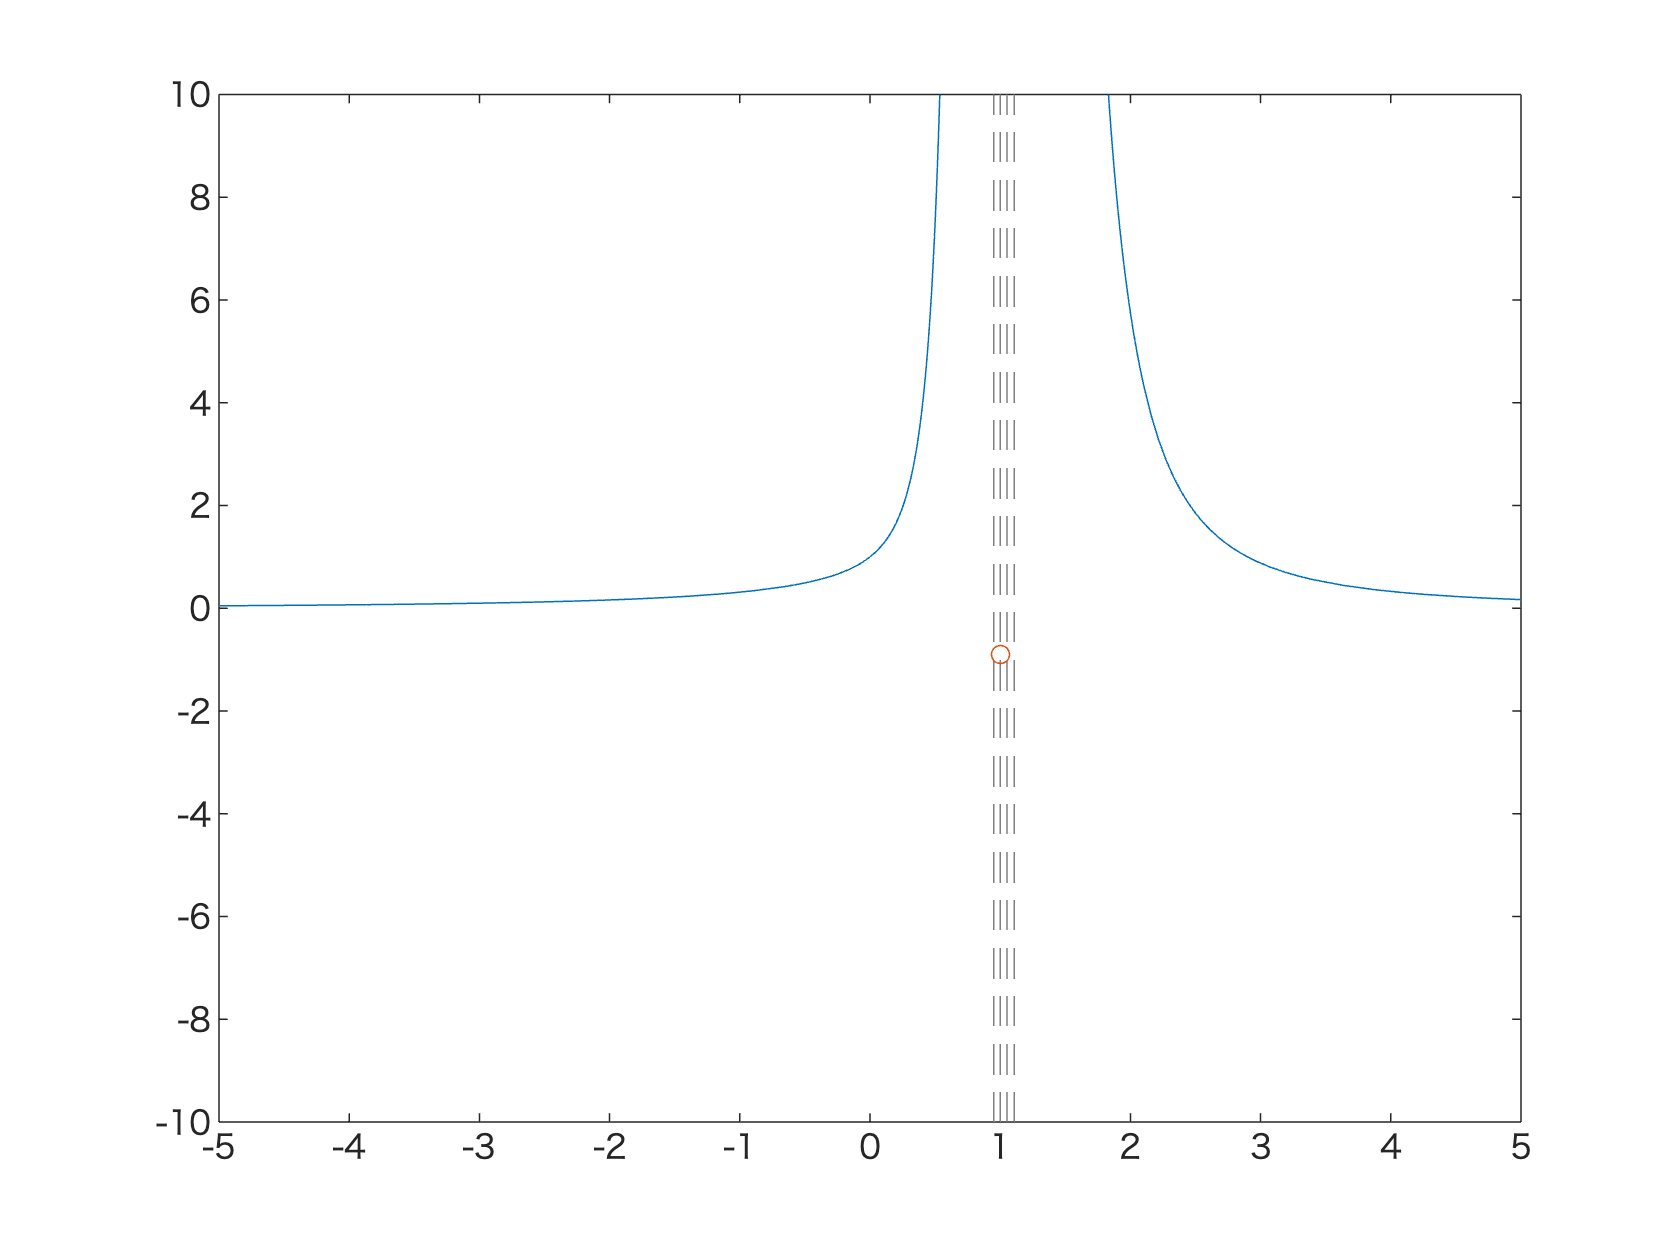

figure(1)
f=subs(expr,q,a);
fplot(f)
hold on 
scatter(1,-a^2)
% for ii=1:6
%     expr=expr*(1-q^(2*ii)*z);
% end
% f=subs(expr,q,a);
% fplot(f)
ylim([-10 10])

% SI((1/(1-q*z)-1/(1-z/q))/(q-q^-1))

n=5;
ii=0:n;
a=-1;
b=2;
sum(binom(n,ii).*polylog0(-2*n+ii,a).*b.^ii)

ans = -0.5000


syms n1 th hb ep
ord=5;
e12=(1+hb^2*n1*(th+1)*(th-n1)/6*(1+hb^2*((5*n1-2)*(th-n1+1)*th-7*n1^2)/60));
e11=exp(hb*(2*n1+th*n1-2*th))*subs(e12,th,n1+th);% binom(th,n)->binom(th+n,n)
e1=taylor(e11,hb,Order=ord+1);
% e1=1+hb*(3*n1^2+5*n1-(n1+2)*th);
e2=fliplr(coeffs(e1,hb,'all'));
r1=length(e2);% hb展開係数の配列の長さ
e5=e2;
e7=e2;
for i1=1:r1
    e4=fliplr(coeffs(e2(i1),n1,'all'));
    r2=0:length(e4)-1;
    e6=e4*stirling2(r2,r2);% n^m展開係数をn!/(n-m)!展開係数に
    e6=e6.*((1-ep)/ep).^r2*(factorial(r2).*binom(-th-1,r2).*(-1).^r2).';
    e5(i1)=e6;
    e8=fliplr(coeffs(e6,th,'all'));
    e7(i1)=1/ep*sum(polylog0(-(0:length(e8)-1),ep^-1).*e8);

end
SI(e5)

SI(-e7*(1-ep))

$$ans = \left(\begin{array}{cccccc} 1 & -\frac{2\,\mathrm{ep}+2}{\mathrm{ep}-1} & \frac{2\,{\mathrm{ep}}^{2}+20\,\mathrm{ep}+2}{{\left(\mathrm{ep}-1\right)}^{2}} & -\frac{4\,{\mathrm{ep}}^{3}+212\,{\mathrm{ep}}^{2}+356\,\mathrm{ep}+4}{3\,{\left(\mathrm{ep}-1\right)}^{3}} & \frac{2\,{\mathrm{ep}}^{4}+472\,{\mathrm{ep}}^{3}+3084\,{\mathrm{ep}}^{2}+2200\,\mathrm{ep}+2}{3\,{\left(\mathrm{ep}-1\right)}^{4}} & -\frac{4\,{\mathrm{ep}}^{5}+3948\,{\mathrm{ep}}^{4}+72608\,{\mathrm{ep}}^{3}+188528\,{\mathrm{ep}}^{2}+80508\,\mathrm{ep}+4}{15\,{\left(\mathrm{ep}-1\right)}^{5}} \end{array}\right)$$

-subs(SI(e7),ep,0).*factorial(0:ord)

$$ans = \left(\begin{array}{cccccc} 1 & 2 & 4 & 8 & 16 & 32 \end{array}\right)$$

-subs(SI(e7),ep,0).*factorial(0:ord)

$$ans = \left(\begin{array}{cccccc} 1 & 2 & 4 & 8 & 16 & 32 \end{array}\right)$$

$\left(\begin{array}{cccccc}

1 & -\frac{2\,\mathrm{ep}+2}{\mathrm{ep}-1} & \frac{2\,{\mathrm{ep}}^2 +20\,\mathrm{ep}+2}{{{\left(\mathrm{ep}-1\right)}}^2 } & -\frac{4\,{\mathrm{ep}}^3 +212\,{\mathrm{ep}}^2 +356\,\mathrm{ep}+4}{3\,{{\left(\mathrm{ep}-1\right)}}^3 } & \frac{2\,{\mathrm{ep}}^4 +472\,{\mathrm{ep}}^3 +3084\,{\mathrm{ep}}^2 +2200\,\mathrm{ep}+2}{3\,{{\left(\mathrm{ep}-1\right)}}^4 } & -\frac{4\,{\mathrm{ep}}^5 +3948\,{\mathrm{ep}}^4 +72608\,{\mathrm{ep}}^3 +188528\,{\mathrm{ep}}^2 +80508\,\mathrm{ep}+4}{15\,{{\left(\mathrm{ep}-1\right)}}^5 }

\end{array}\right)$

syms u
v=u/(1-u);
f=1/v*(1+u)/(1-u)^2+2/v-(3-5*u)/u/(1-u)

$$f = -\frac{2\,\left(u-1\right)}{u}-\frac{u+1}{u\,\left(u-1\right)}-\frac{5\,u-3}{u\,\left(u-1\right)}$$

simplify(f)

$$ans = -\frac{2\,\left(u+1\right)}{u-1}$$

taylor(expand(SI(e5(3))),th)

$$ans = \mathrm{th}\,\left(\frac{31}{3\,{\mathrm{ep}}^{2}}-\frac{61}{3\,\mathrm{ep}}+10\right)-\frac{6}{\mathrm{ep}}+\frac{4}{{\mathrm{ep}}^{2}}+{\mathrm{th}}^{4}\,\left(\frac{1}{2\,{\mathrm{ep}}^{2}}-\frac{1}{\mathrm{ep}}+\frac{1}{2}\right)+{\mathrm{th}}^{3}\,\left(\frac{11}{3\,{\mathrm{ep}}^{2}}-\frac{26}{3\,\mathrm{ep}}+5\right)+{\mathrm{th}}^{2}\,\left(\frac{19}{2\,{\mathrm{ep}}^{2}}-\frac{22}{\mathrm{ep}}+\frac{29}{2}\right)+2$$

q2=taylor(exp(2*hb),hb,Order=ord+1)

$$q2 = \frac{4\,{\mathrm{hb}}^{5}}{15}+\frac{2\,{\mathrm{hb}}^{4}}{3}+\frac{4\,{\mathrm{hb}}^{3}}{3}+2\,{\mathrm{hb}}^{2}+2\,\mathrm{hb}+1$$

e13=sum(SI(-e7*(1-ep)).*hb.^(0:length(e7)-1))

$$e13 = \frac{{\mathrm{hb}}^{2}\,\left(2\,{\mathrm{ep}}^{2}+20\,\mathrm{ep}+2\right)}{{\left(\mathrm{ep}-1\right)}^{2}}-\frac{\mathrm{hb}\,\left(2\,\mathrm{ep}+2\right)}{\mathrm{ep}-1}-\frac{{\mathrm{hb}}^{5}\,\left(4\,{\mathrm{ep}}^{5}+3948\,{\mathrm{ep}}^{4}+72608\,{\mathrm{ep}}^{3}+188528\,{\mathrm{ep}}^{2}+80508\,\mathrm{ep}+4\right)}{15\,{\left(\mathrm{ep}-1\right)}^{5}}-\frac{{\mathrm{hb}}^{3}\,\left(4\,{\mathrm{ep}}^{3}+212\,{\mathrm{ep}}^{2}+356\,\mathrm{ep}+4\right)}{3\,{\left(\mathrm{ep}-1\right)}^{3}}+\frac{{\mathrm{hb}}^{4}\,\left(2\,{\mathrm{ep}}^{4}+472\,{\mathrm{ep}}^{3}+3084\,{\mathrm{ep}}^{2}+2200\,\mathrm{ep}+2\right)}{3\,{\left(\mathrm{ep}-1\right)}^{4}}+1$$

Expr=SI(e13);
Expr(end+1)=SI(Expr(end)-1);
taylor(Expr(end),hb,Order=2)

$$ans = -\frac{\mathrm{hb}\,\left(2\,\mathrm{ep}+2\right)}{\mathrm{ep}-1}$$

Expr(end+1)=SI(Expr(end)-(ep+1)/(1-ep)*(q2-1));
SI(taylor(Expr(end),hb,Order=3))

$$ans = \frac{4\,\mathrm{ep}\,{\mathrm{hb}}^{2}\,\left(\mathrm{ep}+5\right)}{{\left(\mathrm{ep}-1\right)}^{2}}$$

taylor((q2-1)*(q2^2-1),Order=3)

$$ans = 8\,{\mathrm{hb}}^{2}$$

Expr(end+1)=SI(Expr(end)-ep*(ep + 5)/(ep - 1)^2*(q2-1)*(q2^2-1)/2);
SI(taylor(Expr(end),hb,Order=4))

$$ans = -\frac{12\,\mathrm{ep}\,{\mathrm{hb}}^{3}\,\left({\mathrm{ep}}^{2}+10\,\mathrm{ep}+5\right)}{{\left(\mathrm{ep}-1\right)}^{3}}$$

taylor((q2-1)*(q2^2-1)*(q2^3-1),Order=4)

$$ans = 48\,{\mathrm{hb}}^{3}$$

Expr(end+1)=SI(Expr(end)+(ep*(ep^2 + 10*ep + 5))/(ep - 1)^3*(q2-1)*(q2^2-1)*(q2^3-1)/4);
SI(taylor(Expr(end),hb,Order=5))

$$ans = \frac{4\,\mathrm{ep}\,{\mathrm{hb}}^{4}\,\left(13\,{\mathrm{ep}}^{3}+185\,{\mathrm{ep}}^{2}+215\,\mathrm{ep}+67\right)}{{\left(\mathrm{ep}-1\right)}^{4}}$$

taylor((q2-1)*(q2^2-1)*(q2^3-1),Order=4)

$$ans = 48\,{\mathrm{hb}}^{3}$$

Expr2=SI(e13);
Expr2(end+1)=SI(Expr2(end)-1);
taylor(Expr2(end),hb,Order=2)

$$ans = -\frac{\mathrm{hb}\,\left(2\,\mathrm{ep}+2\right)}{\mathrm{ep}-1}$$

Expr2(end+1)=SI(Expr2(end)-(ep+1)/(1-ep)*(q2-1));
SI(taylor(Expr2(end),hb,Order=3))

$$ans = \frac{4\,\mathrm{ep}\,{\mathrm{hb}}^{2}\,\left(\mathrm{ep}+5\right)}{{\left(\mathrm{ep}-1\right)}^{2}}$$

taylor((q2-1)^2,Order=3)

$$ans = 4\,{\mathrm{hb}}^{2}$$

Expr2(end+1)=SI(Expr2(end)-ep*(ep + 5)/(ep - 1)^2*(q2-1)^2);
SI(taylor(Expr2(end),hb,Order=4))

$$ans = -\frac{8\,\mathrm{ep}\,{\mathrm{hb}}^{3}\,\left({\mathrm{ep}}^{2}+13\,\mathrm{ep}+10\right)}{{\left(\mathrm{ep}-1\right)}^{3}}$$

taylor((q2-1)^3,Order=4)

$$ans = 8\,{\mathrm{hb}}^{3}$$

Expr2(end+1)=SI(Expr2(end)+(ep*(ep^2 + 13*ep + 10))/(ep - 1)^3*(q2-1)^3);
SI(taylor(Expr2(end),hb,Order=5))

$$ans = \frac{16\,\mathrm{ep}\,{\mathrm{hb}}^{4}\,\left({\mathrm{ep}}^{3}+26\,{\mathrm{ep}}^{2}+65\,\mathrm{ep}+28\right)}{{\left(\mathrm{ep}-1\right)}^{4}}$$

taylor((q2-1)^4,Order=5)

$$ans = 16\,{\mathrm{hb}}^{4}$$

E2

$$E2 = \begin{array}{l} \left(-\frac{28\,\left(\mathrm{ep}+5\right)}{{\left(\mathrm{ep}-1\right)}^{2}}-\frac{4\,\mathrm{ep}\,\left(198\,{\mathrm{ep}}^{3}+3630\,{\mathrm{ep}}^{2}+9426\,\mathrm{ep}+4026\right)}{\sigma_{1}}\right)\,{\mathrm{hb}}^{5}+\left(\frac{4\,\mathrm{ep}\,\left({\mathrm{ep}}^{4}+116\,{\mathrm{ep}}^{3}+654\,{\mathrm{ep}}^{2}-220\,\mathrm{ep}-551\right)}{\sigma_{1}}-\frac{64\,\left(\mathrm{ep}+5\right)}{3\,{\left(\mathrm{ep}-1\right)}^{2}}\right)\,{\mathrm{hb}}^{4}+\left(\frac{4\,\mathrm{ep}\,\left(-54\,{\mathrm{ep}}^{3}+18\,{\mathrm{ep}}^{2}+126\,\mathrm{ep}-90\right)}{\sigma_{1}}-\frac{12\,\left(\mathrm{ep}+5\right)}{{\left(\mathrm{ep}-1\right)}^{2}}\right)\,{\mathrm{hb}}^{3}+\left(\frac{4\,\mathrm{ep}\,\left(3\,{\mathrm{ep}}^{4}+6\,{\mathrm{ep}}^{3}-36\,{\mathrm{ep}}^{2}+42\,\mathrm{ep}-15\right)}{\sigma_{1}}-\frac{4\,\left(\mathrm{ep}+5\right)}{{\left(\mathrm{ep}-1\right)}^{2}}\right)\,{\mathrm{hb}}^{2}\\ \mathrm{where}\\ \sigma_{1}=3\,{\left(\mathrm{ep}-1\right)}^{5} \end{array}$$

% 単純化したシンボリック式を計算します
simplifiedExpr2 = simplify(E2,"Steps",6400)

$$simplifiedExpr2 = \frac{4\,{\mathrm{hb}}^{2}\,\left({\mathrm{hb}}^{2}+3\right)}{3}-\frac{23040\,{\mathrm{hb}}^{5}}{{\left(\mathrm{ep}-1\right)}^{5}}-\frac{1920\,{\mathrm{hb}}^{4}\,\left(24\,\mathrm{hb}-1\right)}{{\left(\mathrm{ep}-1\right)}^{4}}-\frac{16\,{\mathrm{hb}}^{3}\,\left(379\,{\mathrm{hb}}^{2}-86\,\mathrm{hb}+21\right)}{{\left(\mathrm{ep}-1\right)}^{2}}-\frac{64\,{\mathrm{hb}}^{3}\,\left(448\,{\mathrm{hb}}^{2}-51\,\mathrm{hb}+3\right)}{{\left(\mathrm{ep}-1\right)}^{3}}-\frac{4\,{\mathrm{hb}}^{2}\,\left(73\,{\mathrm{hb}}^{3}-35\,{\mathrm{hb}}^{2}+21\,\mathrm{hb}-6\right)}{\mathrm{ep}-1}$$

## trace formula of q-dilation 

Numerically true (up to 5th order of h)


$${\mathrm{Tr}\;\left(1-u\right)}^{\theta } =\frac{1}{u}\longrightarrow \mathrm{Tr}\;q^{\theta } {\left(u;q\right)}_{\theta } =\frac{1}{u}\;\;\;\;\;\;\;\;\;\;\left(q=e^h \right)$$



$${\mathrm{Tr}\;u}^{\theta } =\frac{1}{1-u}\longrightarrow \mathrm{Tr}\;q^{\theta } {\left(1-u;q\right)}_{\theta } =\frac{1}{1-u}$$


[hb^0~N,θ=0~M-1]


$$q^\theta(1-u;q)_\theta=
u^\theta\sum_{k=0}^\infty \sum_{n=0}^{2k}\frac{h^k}{u^k}p_{n,k}(u)\theta^n\qquad (p_{n,k}(u)\in\mathbb Q[u],~q=e^h)\\
=u^\theta\left(1+h\,{\left(\frac{\theta^2 \,{\left(u-1\right)}}{2\,u}+\frac{\theta \,{\left(u+1\right)}}{2\,u}\right)}+
h^2 \,{\left(\frac{\theta^4 \,{{\left(u-1\right)}}^2 }{8\,u^2 }+\frac{\theta^3 \,{\left(3\,u^2 +2\,u-5\right)}}{12\,u^2 }+\frac{\theta^2 \,{\left(u^2 +3\right)}}{8\,u^2 }+\frac{\theta \,{\left(u-1\right)}}{12\,u^2 }\right)}+\cdots\right)
$$



$$\mathrm{Tr}~ q^\theta(1-u;q)_\theta=\sum_{k=0}^\infty \sum_{n=0}^{2k}\frac{h^k}{u^k}p_{n,k}(u)\mathrm{Li}_{-n}(u)\\
=1+\mathrm{Li}_{0}(u)+
h\,{\left(\frac{ \,{\left(u-1\right)}}{2\,u}\mathrm{Li}_{-2}(u)+\frac{ \,{\left(u+1\right)}}{2\,u}\mathrm{Li}_{-1}(u)\right)}\\
\qquad+h^2 \,{\left(\frac{\,{{\left(u-1\right)}}^2 }{8\,u^2 }\mathrm{Li}_{-4}(u)+\frac{\,{\left(3\,u^2 +2\,u-5\right)}}{12\,u^2 }\mathrm{Li}_{-3}(u)+\frac{\,{\left(u^2 +3\right)}}{8\,u^2 }\mathrm{Li}_{-2}(u)+\frac{ \,{\left(u-1\right)}}{12\,u^2 }\mathrm{Li}_{-1}(u)\right)}+\cdots\\
=\frac{1}{1-u}\qquad\mathrm{(independent~of~}h)$$


N=5;
M=11; %補完的にM>2*Nでないとたぶんだめ
syms hb u
assume(hb^(N+1)==0)
q=taylor(exp(hb),hb,Order=N+1);
e1=sym.zeros(1,M);
e2=sym.zeros(N+1,M);
e3=sym.zeros(N+1,M,M);
for ii=0:M-1
    e1(ii+1)=taylor(qNumS.pch(q,1-u,ii)*exp(hb*ii)+sym(0),hb,Order=N+1);
    e2(:,ii+1)=resize(fliplr(coeffs(e1(ii+1),hb,"All")),N+1);
    for jj=0:N
        e3(jj+1,ii+1,:)=resize(fliplr(coeffs(e2(jj+1,ii+1),u,"All")),M);
    end
end

% qNumS.pch(q,1-u,2)
e2=expand(e2)

e7=SI(e2./(e2(1,:)).*u.^((0:N).'))

% disp(e3)
e6=sym.zeros(N+1,1);
e8=sym.zeros(N+1,2*N+1);
for ii=0:N
    e6(ii+1) = polyfitExact(e7(ii+1,:));
    e8(ii+1,:)=coeffsFixed(e6(ii+1),2*N,sym('n'));
end

e6

e8

polylog0(-(0:2*N),u)

$$ans = \left(\begin{array}{ccccccccccc} 1-\frac{u}{u-1} & \frac{u}{{\left(u-1\right)}^{2}} & -\frac{u^{2}+u}{{\left(u-1\right)}^{3}} & \frac{u^{3}+4\,u^{2}+u}{{\left(u-1\right)}^{4}} & -\frac{u^{4}+11\,u^{3}+11\,u^{2}+u}{{\left(u-1\right)}^{5}} & \frac{u^{5}+26\,u^{4}+66\,u^{3}+26\,u^{2}+u}{{\left(u-1\right)}^{6}} & -\frac{u^{6}+57\,u^{5}+302\,u^{4}+302\,u^{3}+57\,u^{2}+u}{{\left(u-1\right)}^{7}} & \frac{u^{7}+120\,u^{6}+1191\,u^{5}+2416\,u^{4}+1191\,u^{3}+120\,u^{2}+u}{{\left(u-1\right)}^{8}} & -\frac{u^{8}+247\,u^{7}+4293\,u^{6}+15619\,u^{5}+15619\,u^{4}+4293\,u^{3}+247\,u^{2}+u}{{\left(u-1\right)}^{9}} & \frac{u^{9}+502\,u^{8}+14608\,u^{7}+88234\,u^{6}+156190\,u^{5}+88234\,u^{4}+14608\,u^{3}+502\,u^{2}+u}{{\left(u-1\right)}^{10}} & -\frac{u^{10}+1013\,u^{9}+47840\,u^{8}+455192\,u^{7}+1310354\,u^{6}+1310354\,u^{5}+455192\,u^{4}+47840\,u^{3}+1013\,u^{2}+u}{{\left(u-1\right)}^{11}} \end{array}\right)$$

SI(sum(e8.*polylog0(-(0:2*N),u).*u.^(-(0:N)'),2)).'

$$ans = \left(\begin{array}{cccccc} -\frac{1}{u-1} & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


th=sym('theta');
sympref('AbbreviateOutput',false);
disp(sum(SI(e8.*u.^(-(0:N).')).*th.^(0:2*N),2).*sym('h').^((0:N).'))

factorial(9)/1152

ans = 315

e4=polylog0(0:6,2);
polylog0(-2,u)

$$ans = -\frac{u^{2}+u}{{\left(u-1\right)}^{3}}$$

SI((polylog0(-2,u)-polylog0(-1,u))*(u-1)/2/u+polylog(-1,u))

$$ans = 0$$

disp(expand(e2(2,:).'))

$$\left(\begin{array}{c} 0\\ u\\ 3\,u^{2}-u\\ 6\,u^{3}-3\,u^{2}\\ 10\,u^{4}-6\,u^{3}\\ 15\,u^{5}-10\,u^{4}\\ 21\,u^{6}-15\,u^{5}\\ 28\,u^{7}-21\,u^{6} \end{array}\right)$$

disp(e7(3,:).')

$$\left(\begin{array}{c} 0\\ \frac{u^{2}}{2}\\ \frac{u\,\left(9\,u-5\right)}{2}\\ 18\,u^{2}-\frac{31\,u}{2}+2\\ 50\,u^{2}-53\,u+11\\ \frac{225\,u^{2}}{2}-135\,u+35\\ \frac{441\,u^{2}}{2}-\frac{575\,u}{2}+85\\ 392\,u^{2}-\frac{1085\,u}{2}+175 \end{array}\right)$$

e8=sym([]);
e8(4)=polyfitExact(e7(3,:),4)

$$e8 = \left(\begin{array}{cccc} 0 & 0 & 0 & \left(\frac{u^{2}}{8}-\frac{u}{4}+\frac{1}{8}\right)\,n^{4}+\left(\frac{u^{2}}{4}+\frac{u}{6}-\frac{5}{12}\right)\,n^{3}+\left(\frac{u^{2}}{8}+\frac{3}{8}\right)\,n^{2}+\left(\frac{u}{12}-\frac{1}{12}\right)\,n \end{array}\right)$$

e8(3)=polyfitExact(e7(2,:),2)

$$e8 = \left(\begin{array}{cccc} 0 & 0 & \left(\frac{u}{2}-\frac{1}{2}\right)\,n^{2}+\left(\frac{u}{2}+\frac{1}{2}\right)\,n & \left(\frac{u^{2}}{8}-\frac{u}{4}+\frac{1}{8}\right)\,n^{4}+\left(\frac{u^{2}}{4}+\frac{u}{6}-\frac{5}{12}\right)\,n^{3}+\left(\frac{u^{2}}{8}+\frac{3}{8}\right)\,n^{2}+\left(\frac{u}{12}-\frac{1}{12}\right)\,n \end{array}\right)$$


factor(e8(4))

$$ans = \left(\begin{array}{ccccccccc} 1-\frac{u}{u-1} & \frac{u}{{\left(u-1\right)}^{2}} & -\frac{u^{2}+u}{{\left(u-1\right)}^{3}} & \frac{u^{3}+4\,u^{2}+u}{{\left(u-1\right)}^{4}} & -\frac{u^{4}+11\,u^{3}+11\,u^{2}+u}{{\left(u-1\right)}^{5}} & \frac{u^{5}+26\,u^{4}+66\,u^{3}+26\,u^{2}+u}{{\left(u-1\right)}^{6}} & -\frac{u^{6}+57\,u^{5}+302\,u^{4}+302\,u^{3}+57\,u^{2}+u}{{\left(u-1\right)}^{7}} & \frac{u^{7}+120\,u^{6}+1191\,u^{5}+2416\,u^{4}+1191\,u^{3}+120\,u^{2}+u}{{\left(u-1\right)}^{8}} & -\frac{u^{8}+247\,u^{7}+4293\,u^{6}+15619\,u^{5}+15619\,u^{4}+4293\,u^{3}+247\,u^{2}+u}{{\left(u-1\right)}^{9}} \end{array}\right)$$

ans =      5     9


$$ans = \left(\begin{array}{c} -\frac{1}{u-1}\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

$$ans = 0$$


e5=2*expand(e2(3,:).'./u.^((0:M-1).'-2));
e5

$$e5 = \left(\begin{array}{c} 0\\ 0\\ u^{2}-u\\ 9\,u^{2}-13\,u+4\\ 36\,u^{2}-58\,u+22\\ 100\,u^{2}-170\,u+70\\ 225\,u^{2}-395\,u+170\\ 441\,u^{2}-791\,u+350 \end{array}\right)$$

subs(diff(e5,1),0)'

$$ans = \left(\begin{array}{cccccccc} 0 & 0 & -1 & -13 & -58 & -170 & -395 & -791 \end{array}\right)$$

f0=polyfitExact(subs(e5,0))

$$f0(n) = \frac{n^{4}}{4}-\frac{5\,n^{3}}{6}+\frac{3\,n^{2}}{4}-\frac{n}{6}$$

f1=polyfitExact(subs(diff(e5,1),0))

$$f1(n) = -\frac{n^{4}}{2}+\frac{4\,n^{3}}{3}-n^{2}+\frac{n}{6}$$

f2=polyfitExact(subs(diff(e5,2),0))

$$f2(n) = \frac{n^{4}}{2}-n^{3}+\frac{n^{2}}{2}$$

f1(u) = -1/2*u^4 + 4/3*u^3 - u^2 + 1/6*u;
f1(0:M)

$$ans = \left(\begin{array}{ccccccccc} 0 & 0 & -1 & -13 & -58 & -170 & -395 & -791 & -1428 \end{array}\right)$$

SI(subs(f1(u)))

$$ans = -\frac{u\,\left(3\,u^{3}-8\,u^{2}+6\,u-1\right)}{6}$$